Llegim imatge

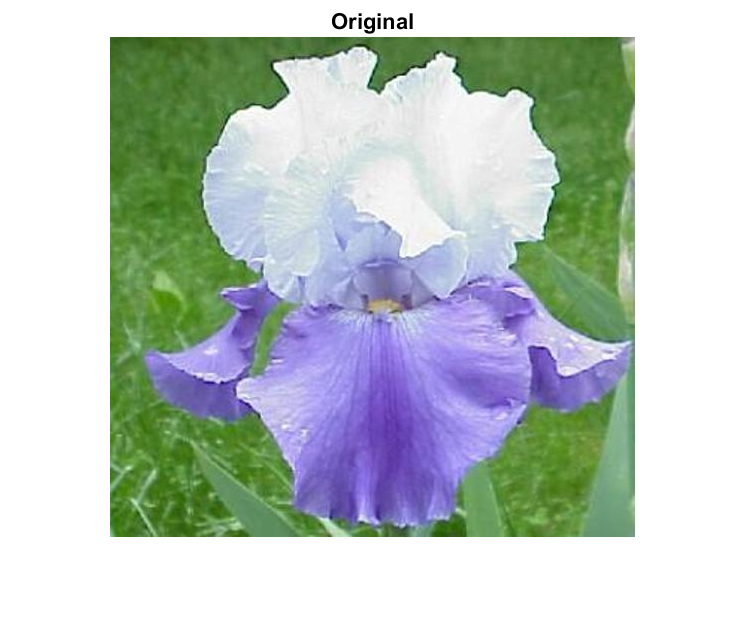

code = 01;
%code = 50;
%code = 80; 
%code = 104;
JPG = ['image_', num2str('0410'), '.jpg'];
   imageJPG = imread(JPG);
   figure, imshow(imageJPG);
   title('Original')

%podríem també normalitzar la imatge

Segmentem per clustering

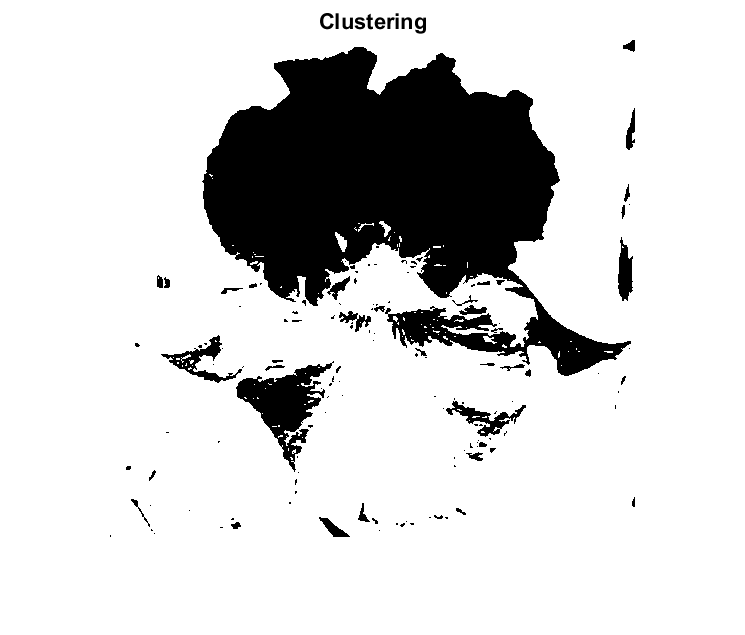

im_aux = imageJPG;
   [L,C] = imsegkmeans(imageJPG,3,'NormalizeInput',true);
im_aux = L > 1;
imshow(double(im_aux),[]), title('Clustering')

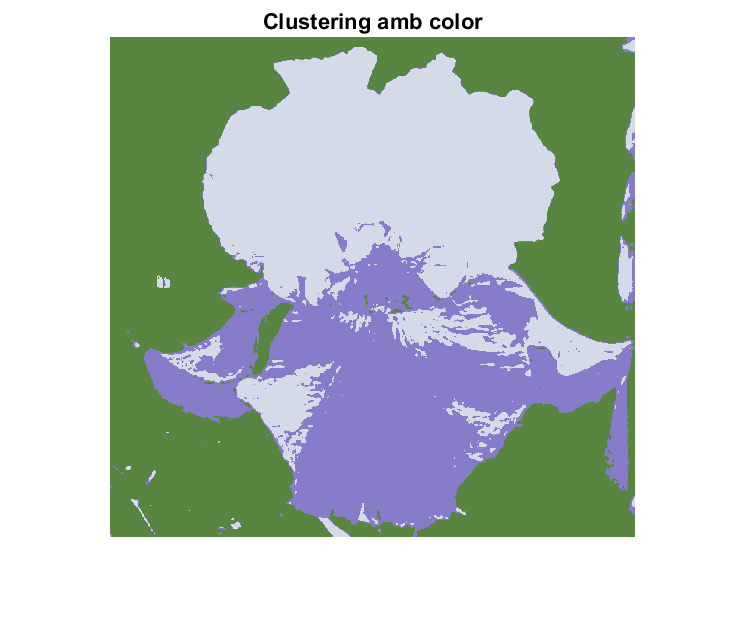

J = label2rgb(L,im2double(C));
imshow(J) , title('Clustering amb color')

Segmentem per binartizació

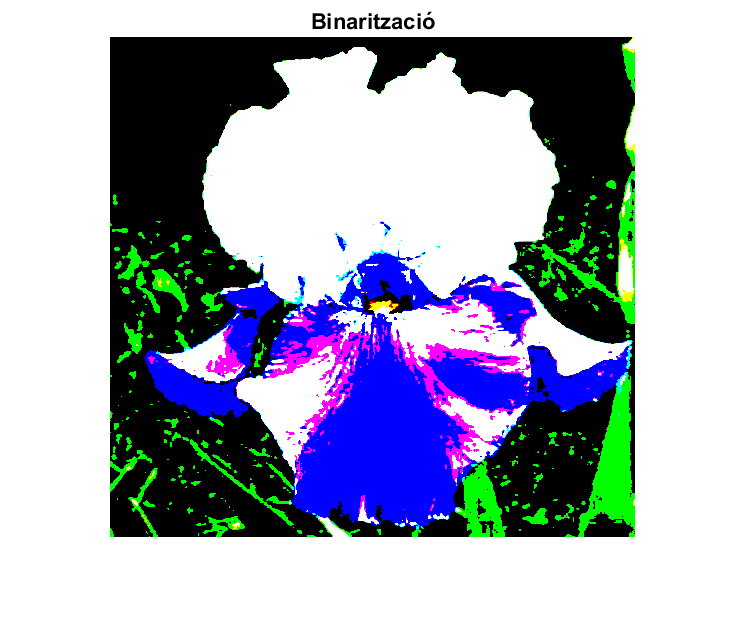

BW = imbinarize(imageJPG,'global');
imshow(double(BW),[]), title('Binarització')

Segmentem per active contour

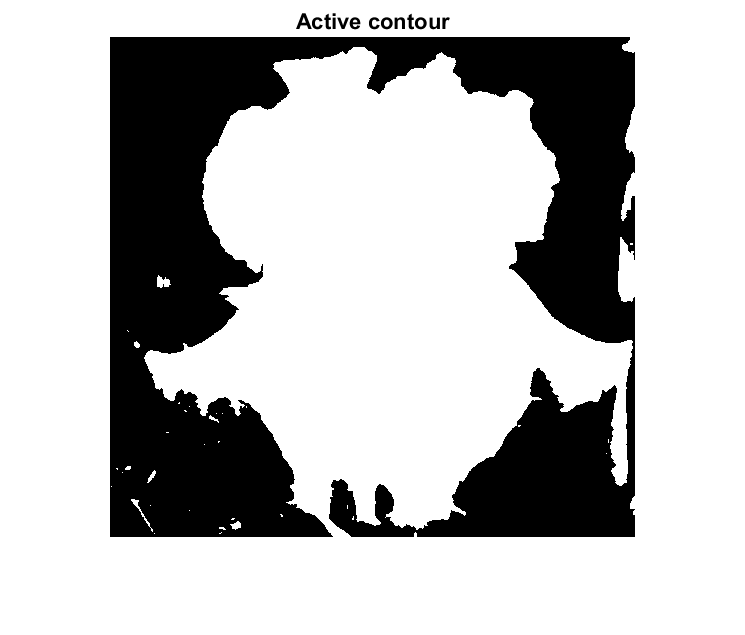

gray = rgb2gray(imageJPG);
mask = zeros(size(gray));
mask(10:end-10,10:end-10) = 1;
%figure, imshow(mask), title('Màscara inicial')
bw = activecontour(imageJPG,mask,500);
figure, imshow(bw)
title('Active contour')

Segmentem fent FastMarching Method, n'hi ha més on pots especificar zones com 

- [https://www.mathworks.com/help/images/ref/imseggeodesic.html](https://www.mathworks.com/help/images/ref/imseggeodesic.html) curiós pq fan servir flors d exemple

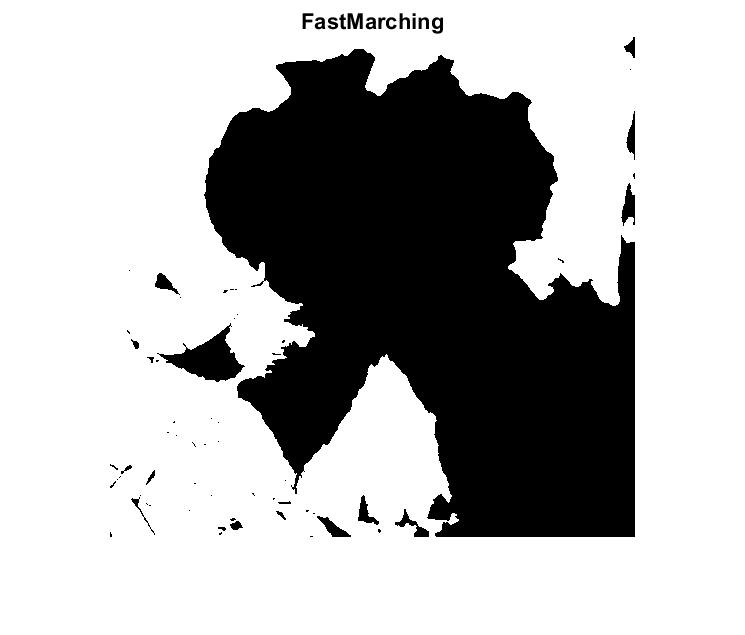

gray = rgb2gray(imageJPG);
mask = false(size(gray));
mask(170,70) = true;
W = graydiffweight(gray,mask,'GrayDifferenceCutoff',60);
thresh = 0.03;
[BW, D] = imsegfmm(W, mask, thresh);
figure
imshow(BW)
title('FastMarching')

S'ha intentat per lazysnapping pro has de fer tu el graph, no es pot fer automàtic. També superpixels